# Derive and apply the inverse Kinematics of a 4-dof Robotic manipulator

In this task we're going to derive and then implement the inverse kinematics for a 4-dof robotic manipulator.  The system that we're going to explore is shown below:

     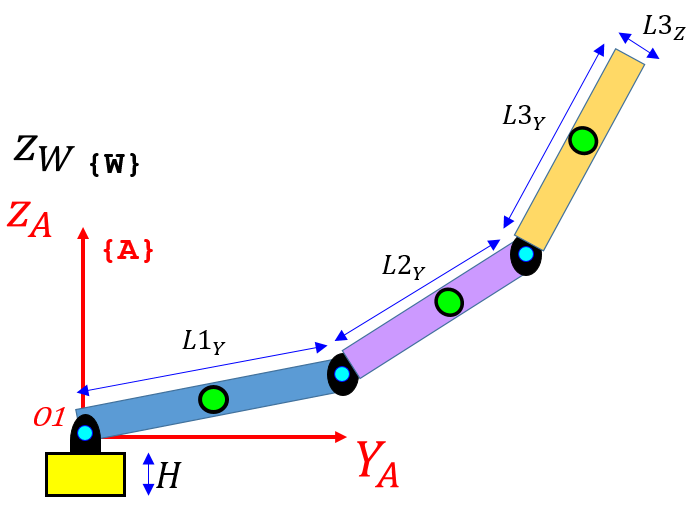   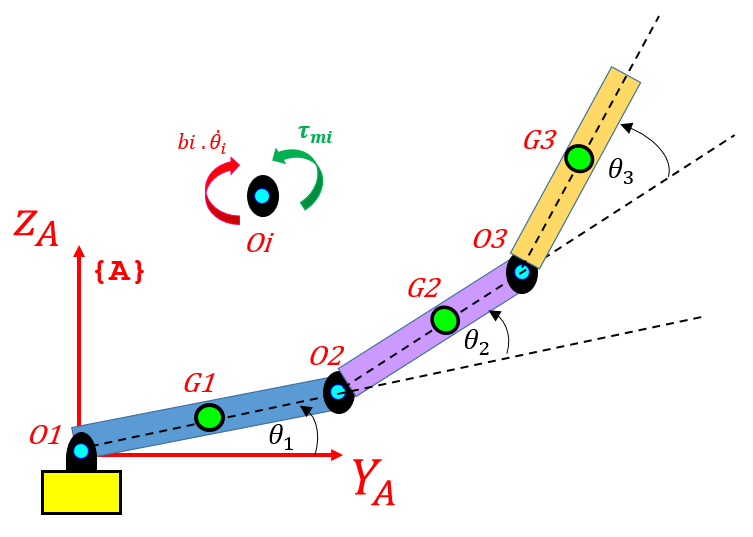   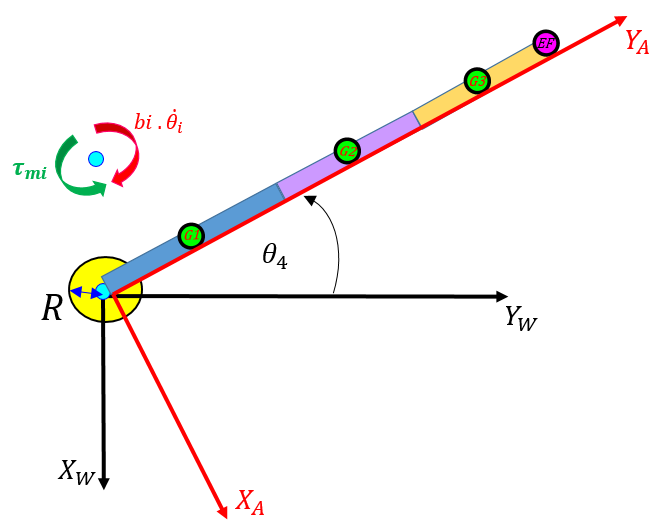   

## Defining some geometry parameters:

syms   L1Y_s L2Y_s L3Y_s 

syms   theta1   
syms   theta2 
syms   theta3
syms   theta4 

syms XE YE ZE

## Define the X,Y position of the End effector:

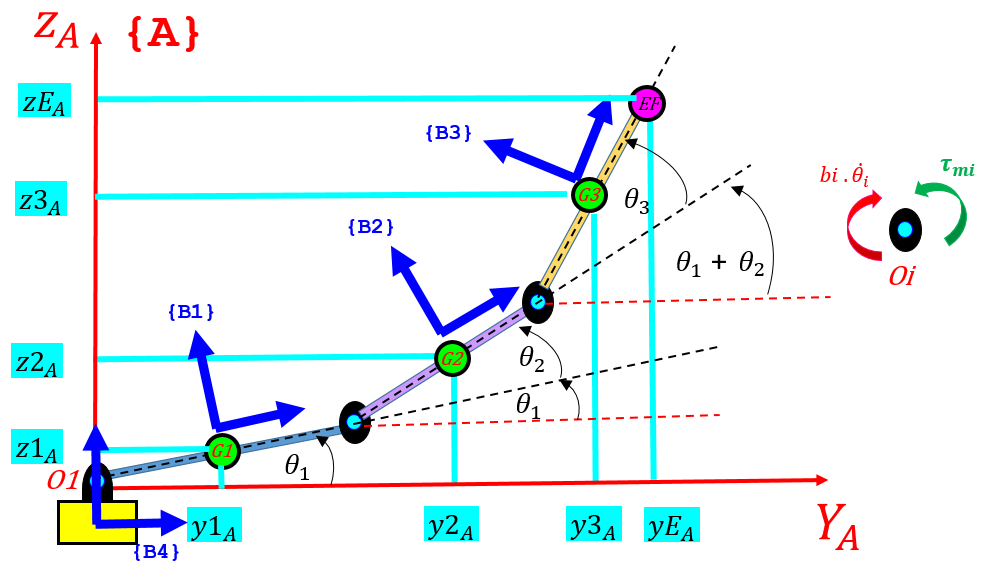     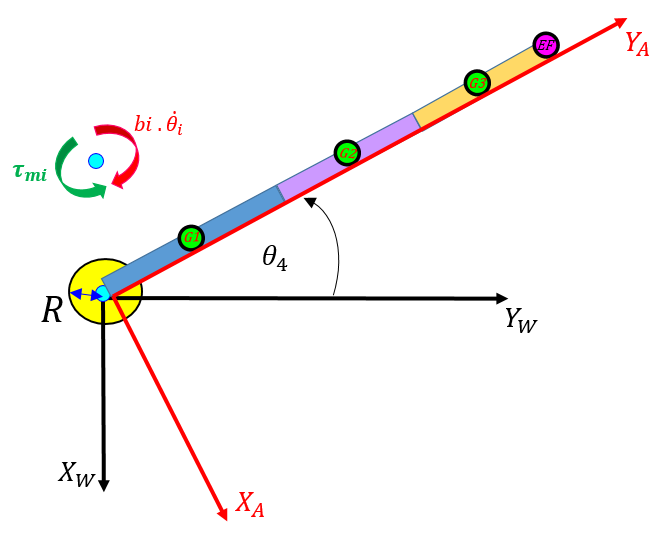

First, let's define the x,y,z position of the End Effector (EF) in terms of the {A}-Frame.  And after we've done this, we'll convert these co-ordinates into our inertial {W}-frame:

A few utility angles to help us:

alpha           = theta1 + theta2;
beta            = theta1 + theta2 + theta3;

OK: so what are the x,y,z co-ordinates of the end effector in components of the {A}-Frame ?

AF_pos_eff      = sym([0;0;0]);
AF_pos_eff(2,1) = L1Y_s*cos(theta1) + L2Y_s*cos(alpha) + L3Y_s*cos(beta);
AF_pos_eff(3,1) = L1Y_s*sin(theta1) + L2Y_s*sin(alpha) + L3Y_s*sin(beta);

We can now convert these {A}-Frame co-ordinates into their corresponding {W}-frame co-ordinates using the following transformation:

   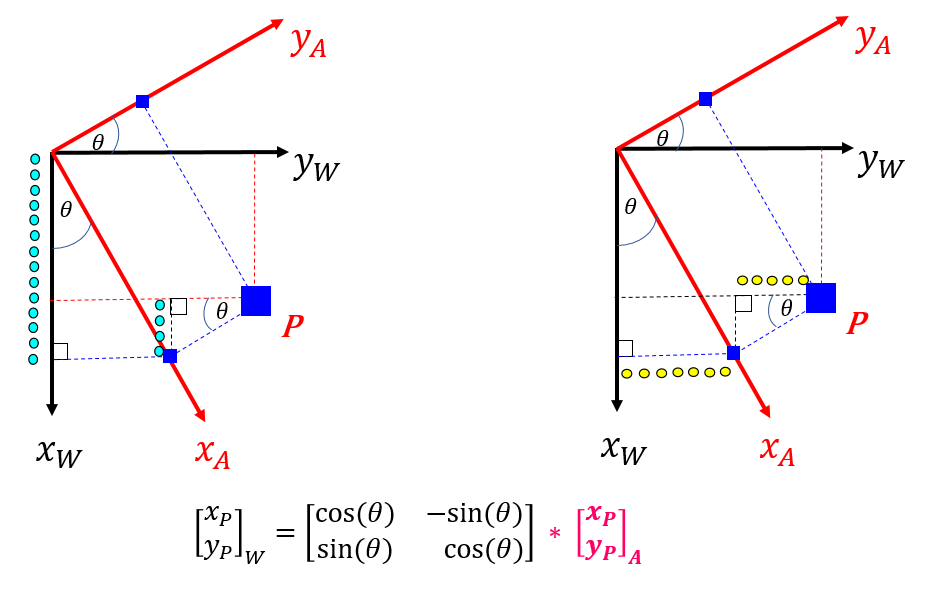

wRa = [ cos(theta4),  -sin(theta4),   0;
        sin(theta4),   cos(theta4),   0;
                  0,             0,   1 ];

So our {W}-Frame end effector co-ordinates are:

WF_pos_eff = wRa * AF_pos_eff;             

Rip out the X,Y,Z elements:

the_XE_RHS = WF_pos_eff(1);
the_YE_RHS = WF_pos_eff(2);
the_ZE_RHS = WF_pos_eff(3);

And I can create a MATLAB function of these END EFFECTOR  forward kinematics:

% matlabFunction([the_XE_RHS, the_YE_RHS, the_ZE_RHS], ...
%    'File', 'bh_xyz_for_4dof_manip')

## Compute the INVERSE  Kinematics:  $(X_E,Y_E,Z_E) \longrightarrow g(X_E, Y_E,Z_E) \longrightarrow (\theta_1, \theta_2, \theta_3, \theta_4)$

     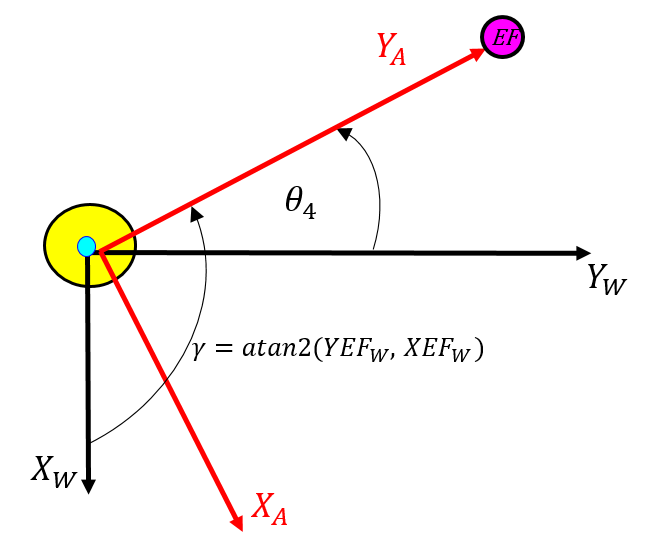     

Solving the inverse kinematics directly using the world frame X,Y,Z co-ordinates is a difficult task.  We could explore breaking the problem into a series of subproblems:

- compute $\theta_4$ immediately using the end effector's $X_W $ and $Y_W$ co-ordinates

- convert the end effector's $X_W $ and $Y_W$into it's corresponding $Y_A$ co-ordinate

- solve for {$\theta_1,\theta_2,\theta_3$ } by considering the {A}-Frame geometry

**Part_1:  solve for **$\theta_4$

Transform the World frame end effector co-ordinates into a new {T}-frame and then solve for $\theta_4$ using the `atan2() `function. An example of this approach using some example numbers, is shown below

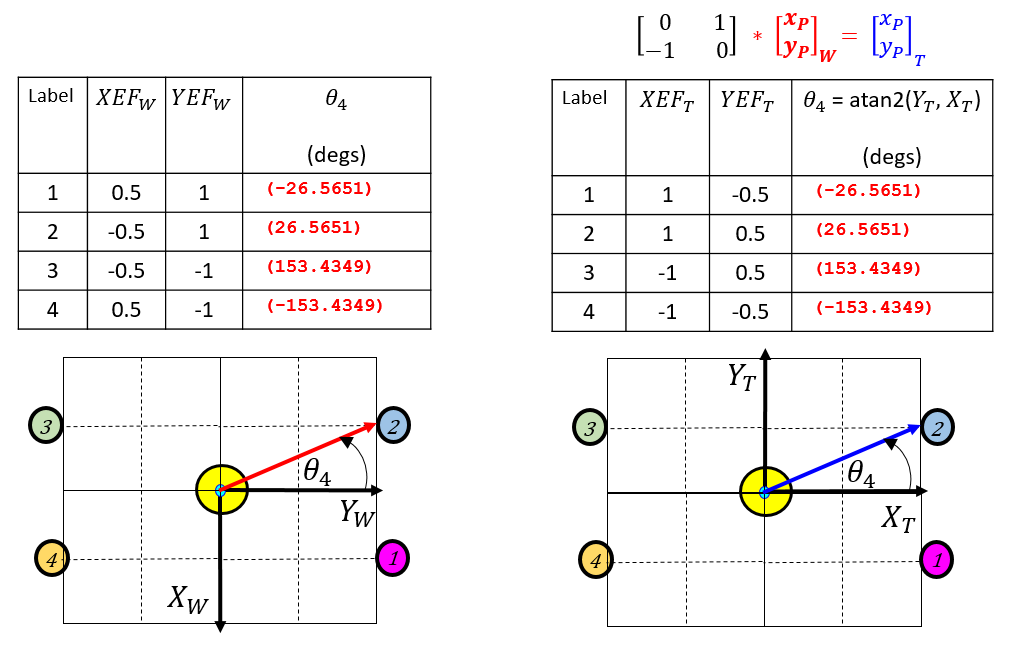

OK - so we can work out $\theta_4$ .... but what about the other 3 angles ?

**Part_2:  convert End effector co-ordinates into the {A}-frame**

Ealier we derived the relationship between co-ordinates in the {W} and {A} frames.  Specifically we derived the following:  

wRa = [ cos(theta4),  -sin(theta4),   0;
        sin(theta4),   cos(theta4),   0;
                  0,             0,   1 ];

So to convert co-ordinates in the {W}-frame into their corresponding co-ordinates in the {A}-Frame, we simply take the transpose of  $^wR_A$, ie:

aRw = wRa.'  ;                

## **Part_3: Solve for **{$\theta_1,\theta_2,\theta_3$ } 

So we assume that we know the end effector's co-ordinates in the {A}-Frame.  Specifically we're interested in the $^AY$ and $^AZ$:

syms YA ZA

So our problem is now:

alpha   = theta1 + theta2;
beta    = theta1 + theta2 + theta3;

the_yA  =  L1Y_s*cos(theta1) + L2Y_s*cos(alpha) + L3Y_s*cos(beta);
the_zA  =  L1Y_s*sin(theta1) + L2Y_s*sin(alpha) + L3Y_s*sin(beta);

And it's apparent that we have 2 equations with 3 unknowns !

*IFFF* you are given(?) the final orientation of the end effector in the {A}-Frame, ie: iff you are given $\Theta = \theta_1+\theta_2+\theta_3$ , then you could reduce the problem to 2 equations and 2 unknowns and solve them much like the 2-dof planar manipulator case.  But there is a "smarter" way ... and it involves the formulation of an optimization problem and then solving for all of the angles.  In this approach we focus on solving a NUMERICAL problem, ie: we'll need to specify numerical values for the lengths of our LINK arms.

# Solving the Inverse KINEMATIC problem numerically:

Let's say that we've got our X,Y,Z trajectory for our END EFFECTOR:

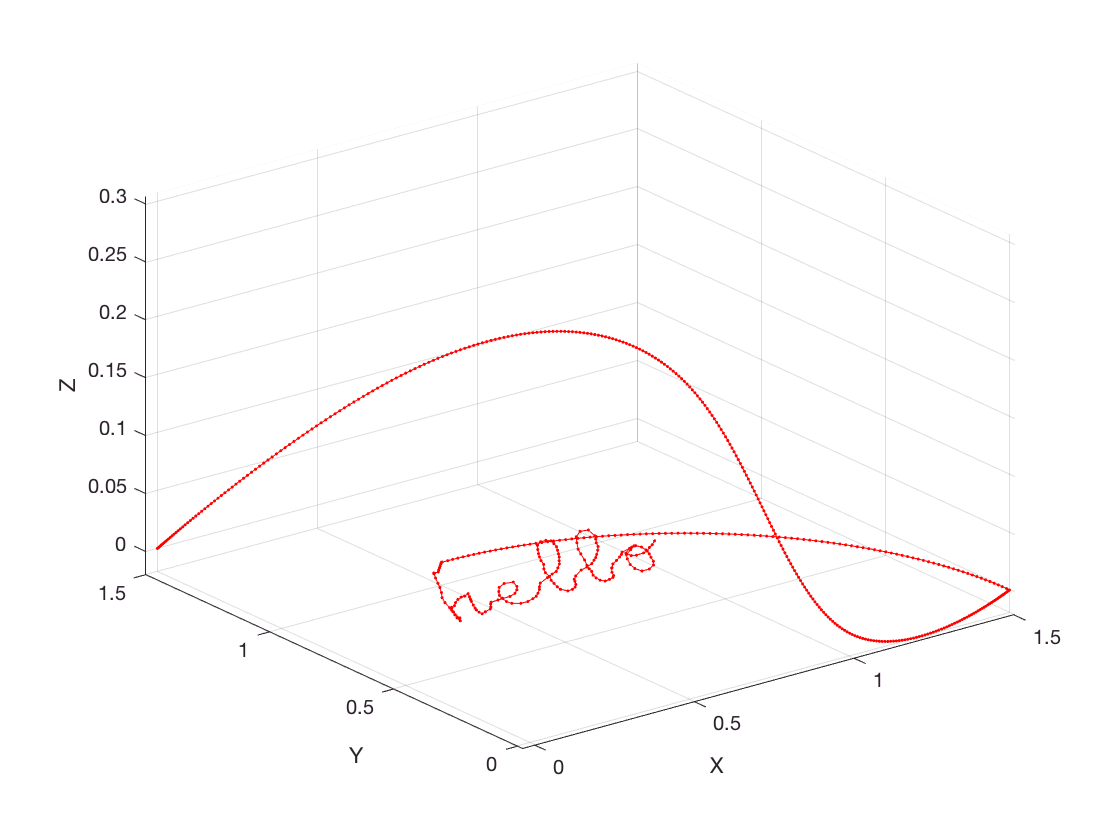

%% read data from EXCEL file
data_T = readtable('bh_hello_complete.xlsx','Sheet','COMP_SPLINE _4dof');

% downsample - say keep every 10th sample
data_T = data_T(1:10:end, :);

% plot it
figure;
plot3(data_T.XE, data_T.YE, data_T.ZE, '-r.');
axis tight; grid on; xlabel X; ylabel Y; zlabel Z

And we'll define the following lengths for our LINKs:

%% Define the LINK lengths
L1 = 0.75;
L2 = 0.5;
L3 = 0.25;

So we're going to formulate and then solve a constrained optimization problem:

opts_T         = optimset;
opts_T.Display = 'off';

Here are the lower and upper bounds for our 4 joint angles:

qa_lb = [ -pi;  -pi;   -pi;    -pi]; % LOWER bounds for angles
qa_ub = [  pi;   pi;    pi;     pi]; % UPPER bounds for angles
qa    = [ 0.5;  0.5;   0.5;    0.5]; % initial guess for 1st data point in trajectory

At the heart of this approach is the utilization of our FORWARD KINEMATICS function:

-    `out1 = bh_xyz_for_4dof_manip(L1Y_s,L2Y_s,L3Y_s,theta1,theta2,theta3,theta4)`

So what we're going to do is define a cost junction made up of the difference between our target end effector X,Y,Z point, and the point computed by our FORWARD KINEMATICS function.  The `fmincon() `solver, will then search for a solution(which are our 4 angles), that minimizes this difference.  Here's how we implement this *- note this section of code takes 80 seconds to run on my laptop.*

N      = size(data_T,1);
Q_RES  = zeros(N, 4);  % container for collecting results

% we'll loop over each point in our end effector's trajectory
for kk=1:N
    if(0==mod(kk,50))
      fprintf('\n .... kk=%4d of %4d',kk, N)    
    end
    
    % the desired END EFFECTOR X,Y,Z position
    tgt_eff_pos = [data_T.XE(kk), data_T.YE(kk), data_T.ZE(kk)];
    
    % the cost function I want to minimize
    my_CF = @(q)( norm( tgt_eff_pos - ...
                        bh_xyz_for_4dof_manip(L1,L2,L3,q(1),q(2),q(3),q(4)) ...
                      ) ...  
                );

    % make my starting guess for the angular pose, the pose computed from
    % the previous point - we'd expect the next solution to be "close by". 
    q0 = qa;
   
    % invoke our optimization solver:
    %x = fmincon(fun,  x0,A, b,Aeq,beq,    lb,    ub, nonlcon, opts)
    qa  = fmincon(my_CF,q0,[],[],[],[], qa_lb, qa_ub, [],      opts_T);

    % store the angular results
    Q_RES(kk,:) = qa.' ;
end


 .... kk=  50 of  570
 .... kk= 100 of  570
 .... kk= 150 of  570
 .... kk= 200 of  570
 .... kk= 250 of  570
 .... kk= 300 of  570
 .... kk= 350 of  570
 .... kk= 400 of  570
 .... kk= 450 of  570
 .... kk= 500 of  570
 .... kk= 550 of  570

Plot the target END EFFECTOR position versus what we can deliver with our joint solution:

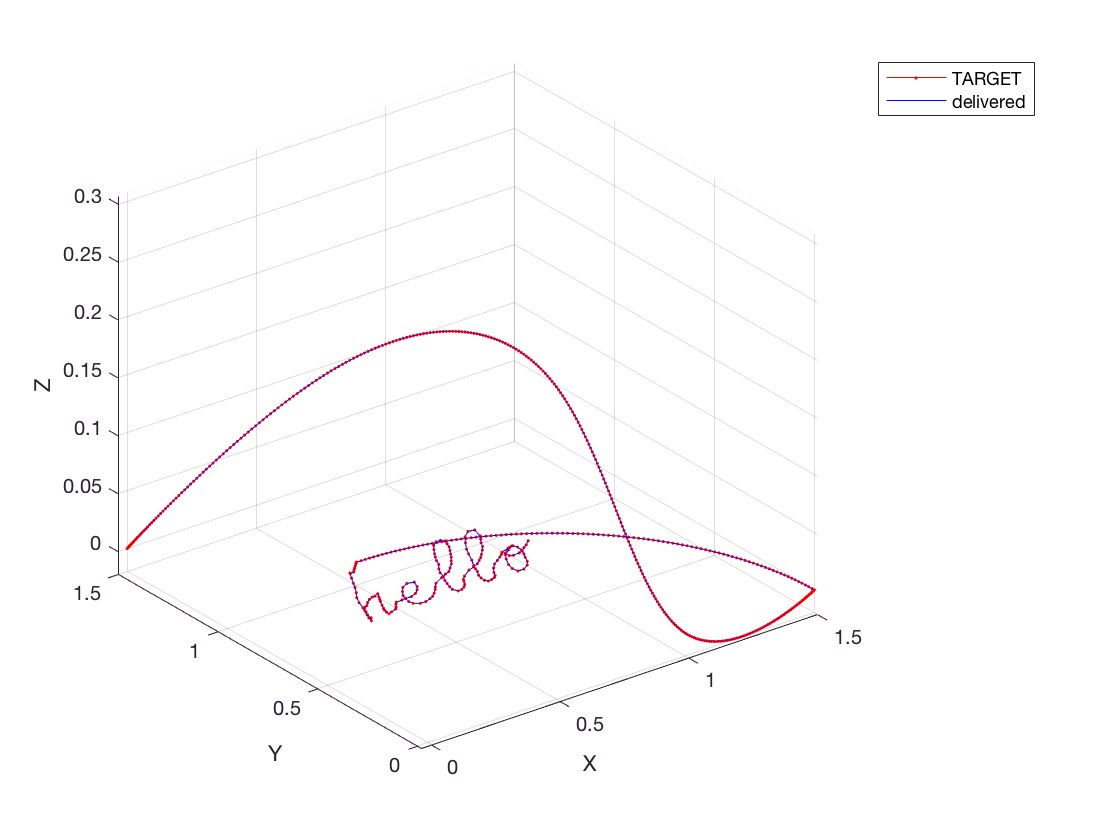

our_sol_XYZ = bh_xyz_for_4dof_manip(L1,L2,L3, Q_RES(:,1), Q_RES(:,2), Q_RES(:,3), Q_RES(:,4) );

figure;
    plot3(      data_T.XE,         data_T.YE,       data_T.ZE, '-r.');  hold on;
    plot3(our_sol_XYZ(:,1),  our_sol_XYZ(:,2),our_sol_XYZ(:,3), '-b');  
    axis tight; grid on; xlabel X; ylabel Y; zlabel Z;
    legend({'TARGET','delivered'})

Plot the joint angles

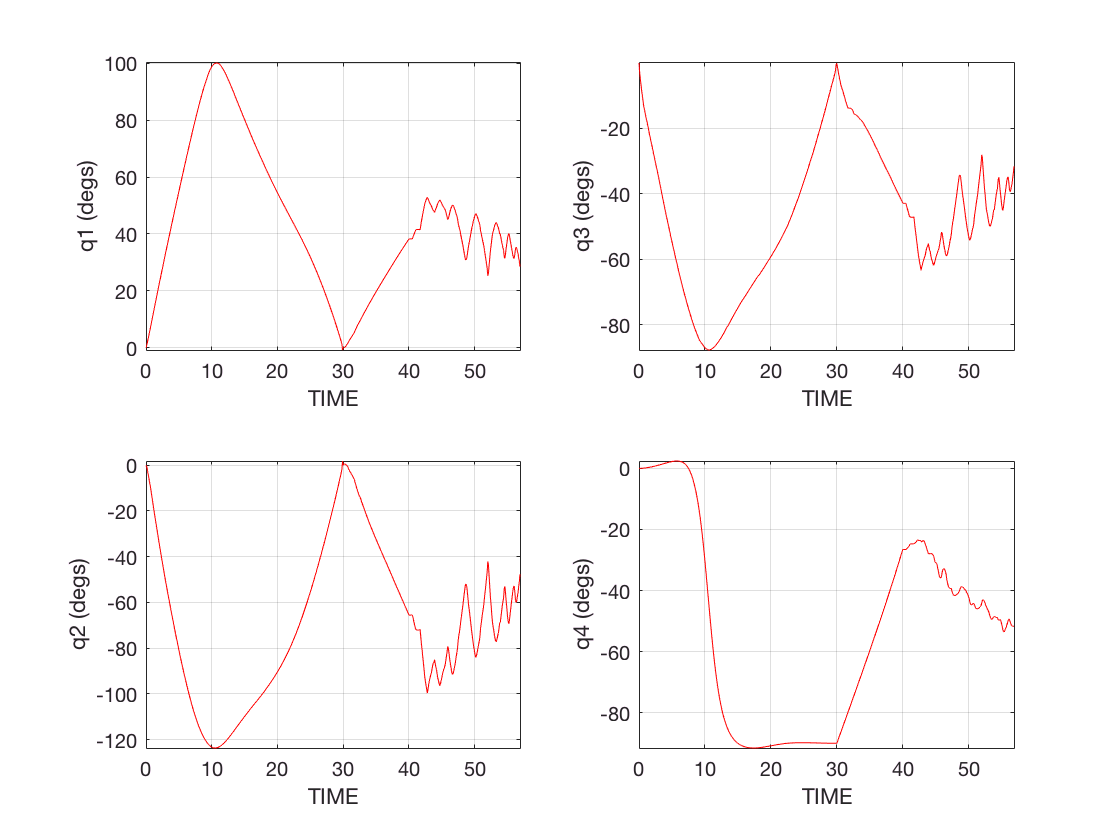

Q_degs_RES = (180/pi)*Q_RES;
T          = data_T.T;
figure;
subplot(2,2,1);  plot(T, Q_degs_RES(:,1), '-r'); 
                 grid on; xlabel TIME; ylabel('q1 (degs)'); axis tight;
subplot(2,2,3);  plot(T, Q_degs_RES(:,2), '-r'); 
                 grid on; xlabel TIME; ylabel('q2 (degs)'); axis tight;
subplot(2,2,2);  plot(T, Q_degs_RES(:,3), '-r'); 
                 grid on; xlabel TIME; ylabel('q3 (degs)'); axis tight;
subplot(2,2,4);  plot(T, Q_degs_RES(:,4), '-r'); 
                 grid on; xlabel TIME; ylabel('q4 (degs)'); axis tight;                 